# Reconstruction using modified spacetime analysis

This document aims to conduct the modified peak finding method and further spacetime analysis reconstruction. Some parameters require change for each individual capturing. Those parameters will be ***highlighted and separated from other command lines.***

**It is recommended to run the code section by section.**

## 1 Read data

***name of the video changes, before you do so, you need to set the current folder to where you store the video***

tic
v = VideoReader("1-2.MP4"); 

You might experience this error: Failed to initialize internal resources. It can be fixed by downloading a multimedia codecs pack. I used a [K-Lite Codec Pack](https://codecguide.com/download_kl.htm) for Windows. You can use other packages as you like.

## 2 Background and ROI

considering the last frame as the background (generally no laser stripes)

In this example, I applied an ROI to reduce the computation in sections 3 & 4 (for illustration purpose). But I didn't apply it to all the calculation steps (e.g., sections 5, 6). If you want to make your own version of this work, it is better to apply it.

We use the first frame to decide the target region.

frame_first = read(v,1);            % read the first frame
imshow(frame_first);                % present the first frame for you to decide ROI

toc

Elapsed time is 1.371743 seconds.


select two points in the images as the left top and right bottom points of your ROI -> Rectangle shape ROI

***Manually select the ROI as the observation window, it will change everytime you have a new video.***

indexX1 = 1838;
indexY1 = 714;
indexX2 = 3566;
indexY2 = 2346;

## 3 Find suitable threshold value for peak searching (sample some points to analyse)

This part comes from the section 2.3.4 Spacetime analysis-based peak searching method for concrete material in [3D reconstruction of concrete defects using optical laser triangulation and modified spacetime analysis](https://www.sciencedirect.com/science/article/abs/pii/S0926580522003429). As we mentioned in the introduction of spacetime analysis, we want to analyse the intensity distribution of a single pixel, find it peak and the corresponding frame.

As the distribution might be different between videos due to varied ambient light conditions, we want to find the general patterns on the selected points. Then, apply the pattern to all the points in ROI. 

Here is an example of [36 selected points](https://ars.els-cdn.com/content/image/1-s2.0-S0926580522003429-gr10.jpg) forming an observation matrix:

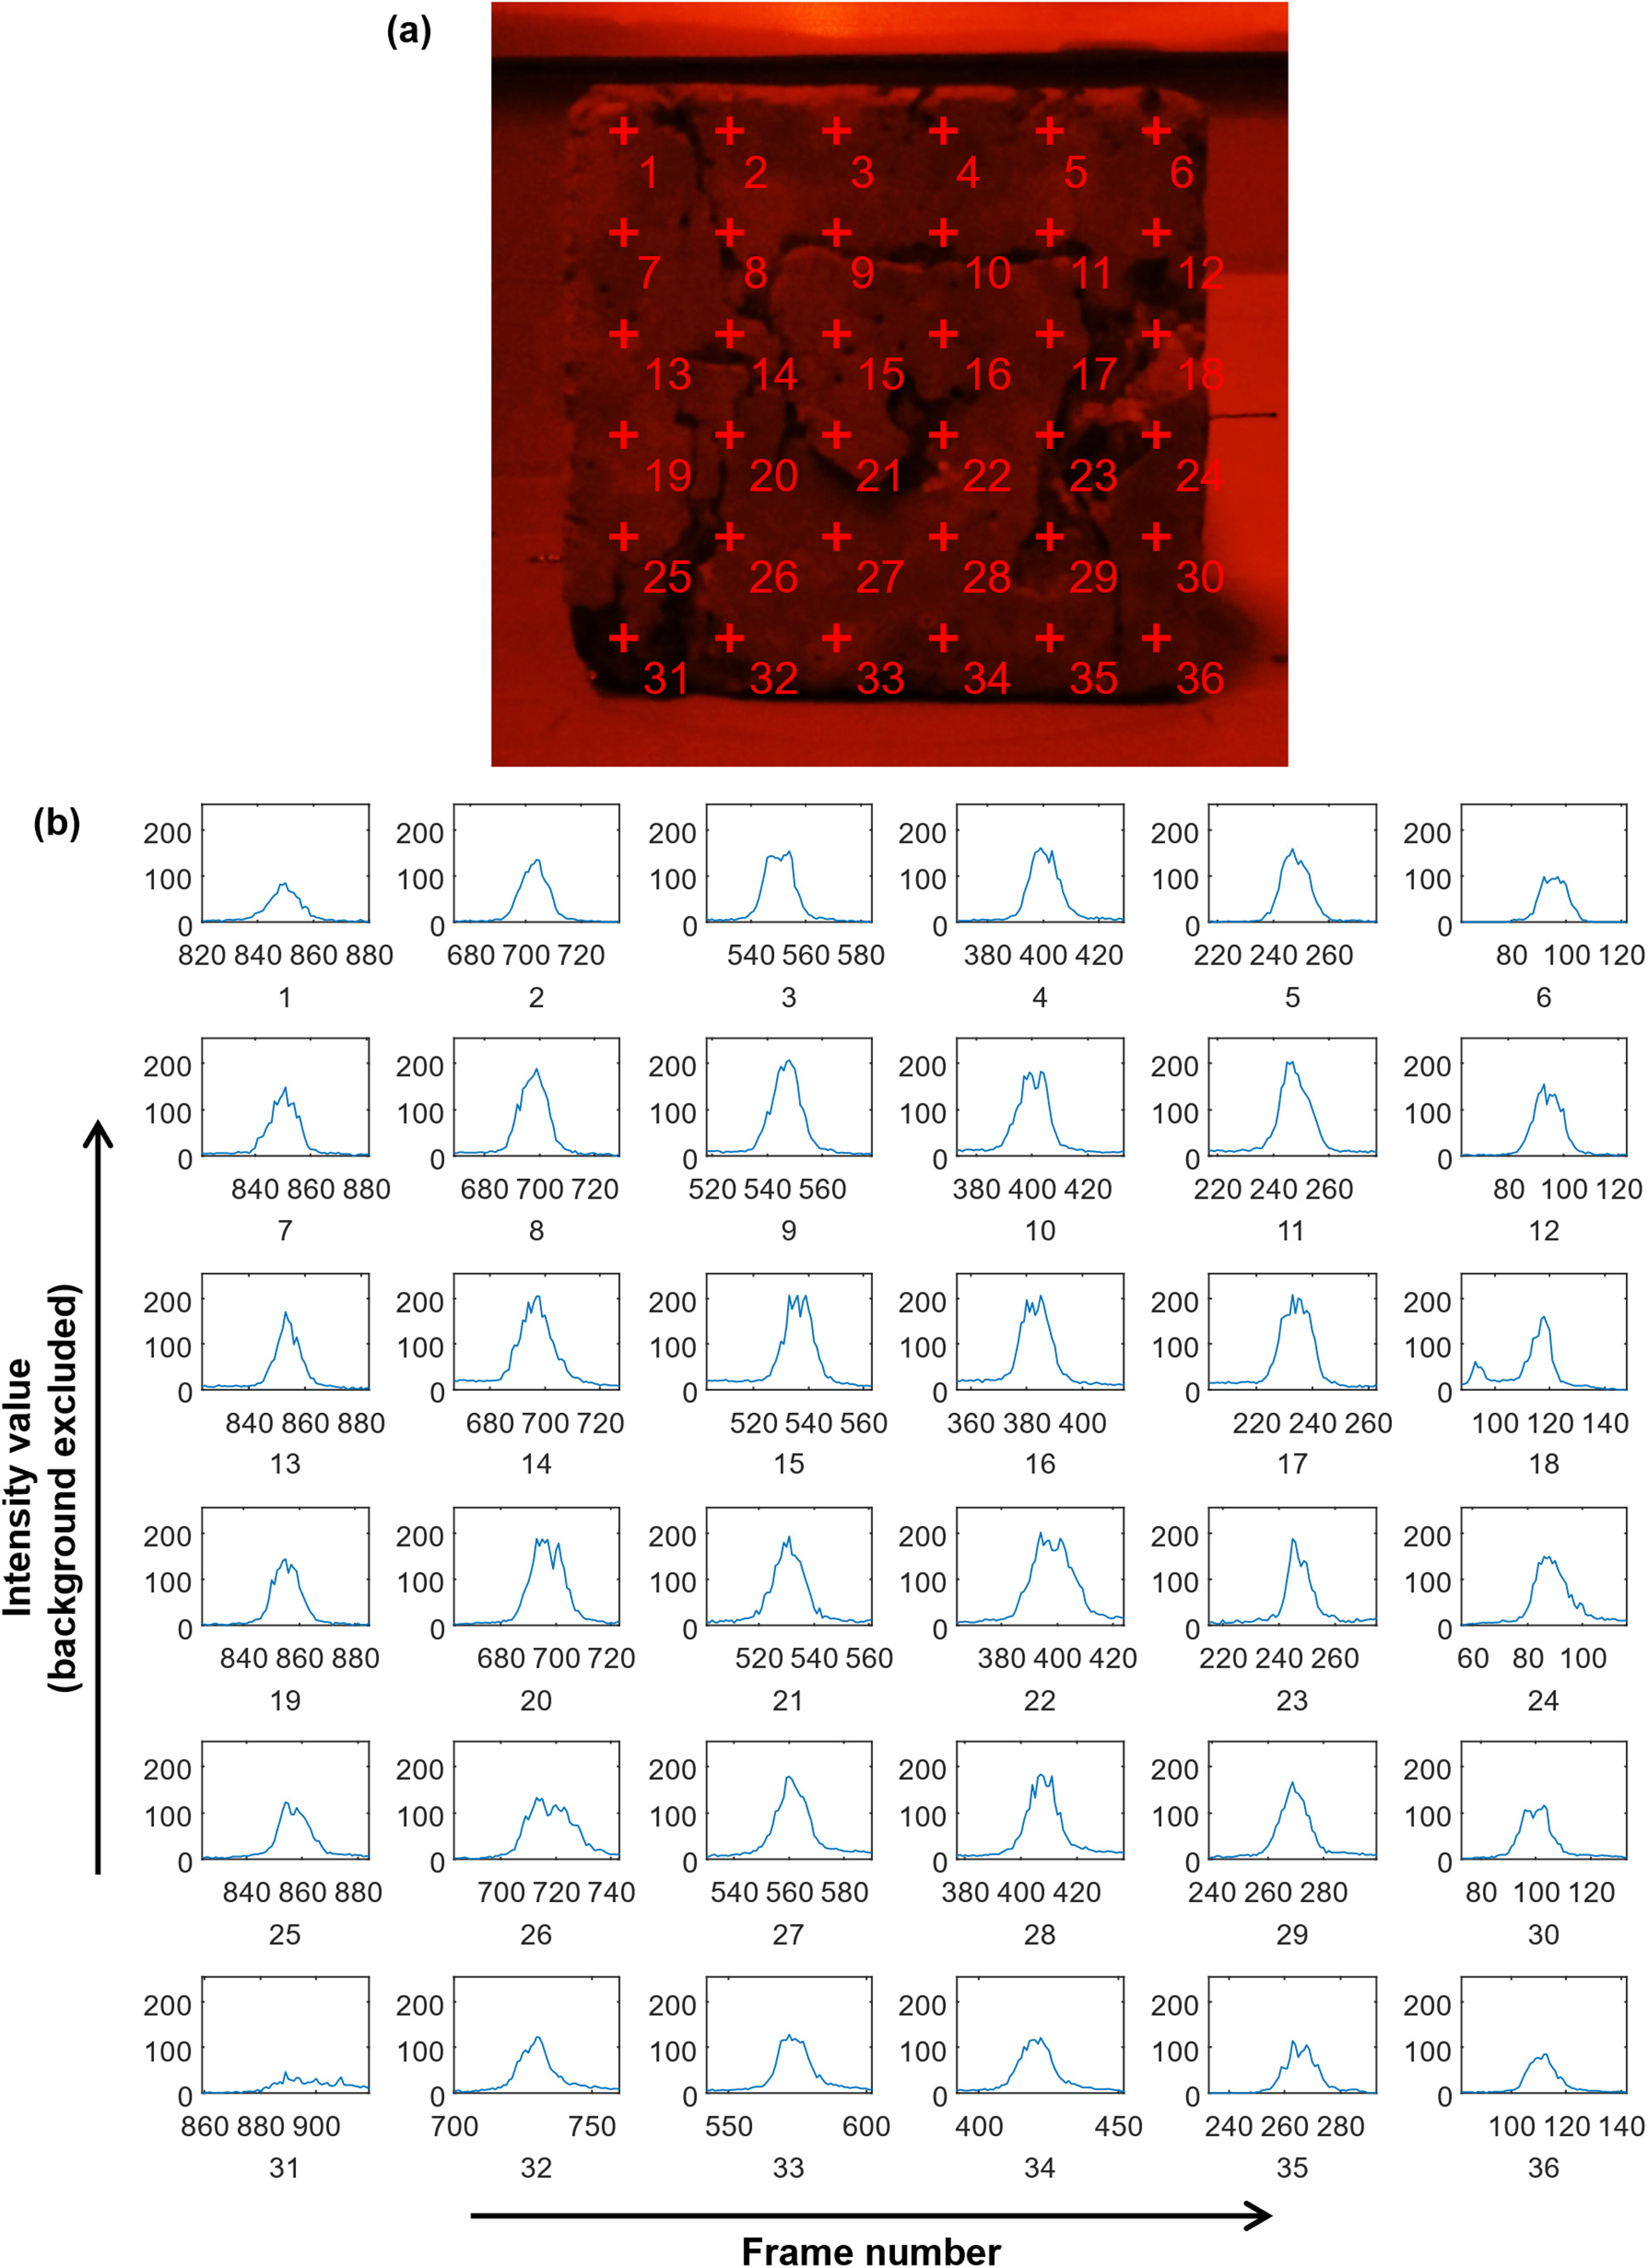

Instead of the searching for the peak point, we believe that it is more stable to study the left (entry) and right (exit) slopes (middle section in the following image) which might be more stable. **To do so, we need to decide the high/low limits which define the middle section**. Then, how to find it? We want the absolute values of the left & right slopes can be as close as possible. We want $\Delta {\;}_{\mathbf{slope}} =\left|\left|\mathbf{slope}\;\mathbf{of}\;\mathbf{entry}\right|-\left|\mathbf{slope}\;\mathbf{of}\;\mathbf{exit}\right|\right|$ to be relatively small and stable for all selected pixels.

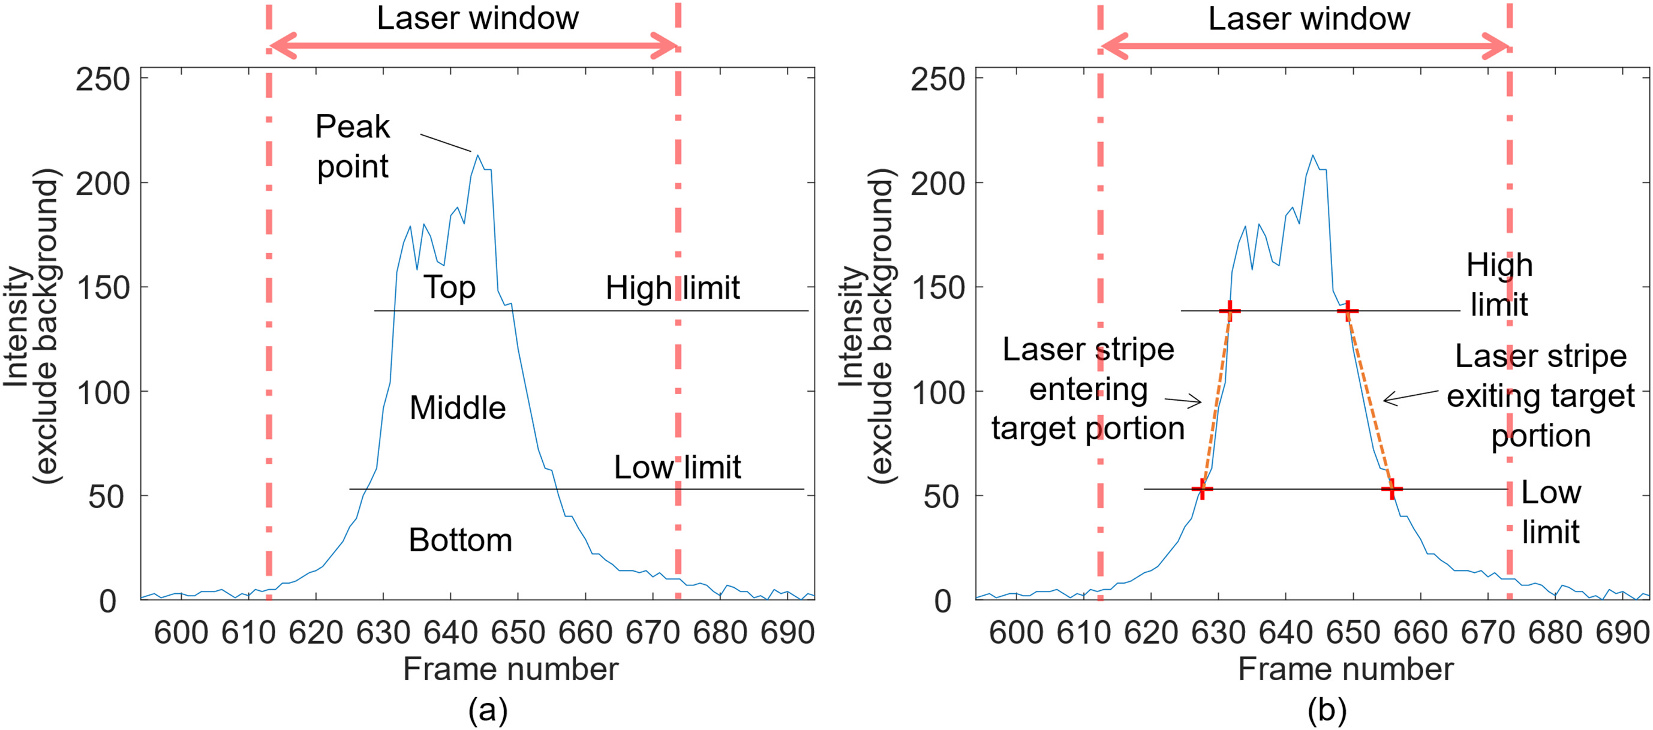

***You need to decide the density of the observation points (n*n matrix)***

num_gaps = 13;% must be a odd number to make sure the matrix at the centre of your ROI

generate the index for the observation matrix

a = round(linspace(indexX1,indexX2,num_gaps))

a =         1838        1982        2126        2270        2414        2558        2702        2846        2990        3134        3278        3422        3566


b = round(linspace(indexY1,indexY2,num_gaps))

b =          714         850         986        1122        1258        1394        1530        1666        1802        1938        2074        2210        2346


go through the video, find and store the **red channel intensity** of the selected pixels (note that the intensity log is background excluded)

`value_pixel --- used to store the intensity log of selected pixels along the video`

value_pixel = zeros(size(a,2),size(b,2),v.NumFrames); % reserve the space to accelerate

tic
% read all the selected points and store the red channel
for i = 1:1:v.NumFrames
    frame_c = read(v,i);
    for i_ = 1:size(a,2)            % x index of the selected pixel
        for j_ = 1:size(b,2)        % y index of the selected pixel
            value_pixel(j_,i_,i) = im2double(frame_c(b(j_),a(i_),1)-frame_e(b(j_),a(i_),1));% store the intensity at frame i
        end
    end
end

toc

Elapsed time is 81.241765 seconds.


Read the maximum intensity (in `M`) of those pixels and the corresponding Frame number (in` I`) -- prepare for the next step of slope finding

We find the (first) maximum value and the corresponding frame number as the processing in the next step will start from the maximum point to the start and the end of the intensity log.

M = [];
I = [];
[M,I] = max(value_pixel,[],3);

% excludevalue = M<=0.15
% M(excludevalue == 1) = 1
% I(excludevalue == 1) = NaN
% x_slope =  + find_frame_low_left-find_frame_high_left

## 4 Find suitable threshold value for peak searching (search for the suitable low/high limits)

This section aims to find the two slopes defined by the intersections (two on left side of peak and two on the other side). 

To find a suitable limit combination, we search all combinations of **low/high limits** -> low limit from 0.20 to 0.85; high limit from low limit to 0.95. Searching step is 0.05. The two limits generate two parallel lines to the x axis (Frame axis) which cut the intensity log into three sections: Top, Middle, and Bottom. **This cutting will have four intersections which can be used to determine the two slope values.** I put this image here for illustration.

You must make sure that all the pixels can be viewed by the laser stripe! This code doesn't cover exception cases.

Find the combination that makes the two slopes symmetric or at least look like symmetric. ***Index is the mean and standard deviation of the absolute value of the difference between the absolute value of the two slopes.***

checklist = []; % checklist stores the pair of low/high limits, and the corresponding slope difference
count = 0;

tic

for low_limit = 0.20:0.05:0.75                  % go through all combinations 
    for high_limit = low_limit+0.05:0.05:0.85   % ...
        slope = [];                             % initialize slope array every new combination
        slope_difference = [];                  % initialize slope difference array (absolute value)
        for testx = 2:size(value_pixel,1)-1     % ignore the data close to boundary
            for testy = 2:size(value_pixel,2)-1 % ...
                high_designvalue = high_limit * value_pixel(testx,testy,I(testx,testy));    % two design values specified for each point
                low_designvalue = low_limit * value_pixel(testx,testy,I(testx,testy));      % formula is: limit * maximum value at this pixel

                find_frame_high_left = [];      % initialize array storing left intersection at high limit
                find_frame_low_left = [];       % ... at low limit
                find_frame_high_right = [];     % initialize array storing right intersection at high limit
                find_frame_low_right = [];      % ... at low limit

                % first loop for left two points
                for frame_ = I(testx,testy):-1:max(I(testx,testy)-100,1)        % search from the peak point to 100 frames forward (from maximum, and decrease)
                % in this loop, two if section to decide which point to store
                    if isempty(find_frame_high_left)                            % if you haven't found the left high intersection, continue
                        if value_pixel(testx,testy,frame_) < high_designvalue   % if you found sth less than high design value, store it
                            find_frame_high_left = frame_ + ...                 % linear interpolation to find the intersection
                                (high_designvalue-value_pixel(testx,testy,frame_))/...
                                (value_pixel(testx,testy,frame_+1)-value_pixel(testx,testy,frame_));
                        end
                    end
                    if isempty(find_frame_low_left)                             % if you haven't found the left low intersection, continue
                        if value_pixel(testx,testy,frame_) < low_designvalue
                            find_frame_low_left = frame_ + ...
                                (low_designvalue-value_pixel(testx,testy,frame_))/...
                                (value_pixel(testx,testy,frame_+1)-value_pixel(testx,testy,frame_));
                        end
                    else
                        break                                                   % if you have found the left low intersection, break this loop
                    end                                                         % find the left low means you finish the searching at this pixel
                end

                x_slope = [];
                if isempty(find_frame_low_left)
                    find_frame_low_left = 0.0001;
                end
                if isempty(find_frame_high_left)
                    find_frame_high_left = 0.0001;
                end                
                x_slope = find_frame_low_left-find_frame_high_left;             % frame number, and avoid empty set
                y_slope = [];
                y_slope = (high_limit-low_limit)*255*value_pixel(testx,testy,I(testx,testy)); % intensity value in 0-255 (still double)
                slope_left = abs(y_slope/x_slope);                              % with the setting, the slope will be very large if you have an empty x difference

                % second loop for right two points, same as the above but opposite searching direction               
                for frame_ = I(testx,testy):1:min(I(testx,testy)+100,v.NumFrames) % search from the peak point to 100 frames backward
                    if isempty(find_frame_high_right)
                        if value_pixel(testx,testy,frame_) < high_designvalue
                            find_frame_high_right = frame_ - ...
                                (high_designvalue-value_pixel(testx,testy,frame_))/...
                                (value_pixel(testx,testy,frame_-1)-value_pixel(testx,testy,frame_));
                        end
                    end
                    if isempty(find_frame_low_right)
                        if value_pixel(testx,testy,frame_) < low_designvalue
                            find_frame_low_right = frame_ - ...
                                (low_designvalue-value_pixel(testx,testy,frame_))/...
                                (value_pixel(testx,testy,frame_-1)-value_pixel(testx,testy,frame_));
                        end
                    else
                        break
                    end
                end
                x_slope = [];
                if isempty(find_frame_low_right)
                    find_frame_low_right = 0.0001;
                end
                if isempty(find_frame_high_right)
                    find_frame_high_right = 0.0001;
                end
                x_slope = find_frame_low_right-find_frame_high_right;
                y_slope = [];
                y_slope = (high_limit-low_limit)*255*value_pixel(testx,testy,I(testx,testy));
                slope_right = abs(y_slope/x_slope);
        
                slope_difference(testx,testy) = abs(slope_left-slope_right);
            end
        end
        
        % slope difference will be initialized at every combination
        % so use slope_forcheck to store the results
        slope_forcheck = slope_difference(2:size(value_pixel,1)-1,2:size(value_pixel,2)-1); % only consider the selected points (exclude the boundary)
        meanvalue = mean(mean(slope_forcheck(slope_forcheck<999)));                         % mean of all slope difference; exclude the error caused by empty sets
        stdvalue = std(slope_forcheck(slope_forcheck<999),1,'all');                         % std of ...
        count = count + 1;                                                                  % count how many combinations for now
        checklist(count,1) = low_limit;
        checklist(count,2) = high_limit;
        checklist(count,3) = meanvalue;
        checklist(count,4) = stdvalue;
    end
end

toc

Elapsed time is 0.528518 seconds.


checklist contains the limit pair, mean, and std of slope difference.

Now, we want to find the suitable pair which can generate the minimum mean or std. In this work, std is selected as I want a stable result.

[minimumstd,indexstd] = min(checklist(:,4),[],'all','linear') % select the pair which generate the minimum std

minimumstd = 3.5709

indexstd = 10

low_limit = checklist(indexstd,1)

low_limit = 0.2000

high_limit = checklist(indexstd,2)

high_limit = 0.7000

With the chosen pair of low/high limits, go through the whole video and find the theoretical position for the peak.

**I won't deny that it is a very complex process. Why don't we simply apply Gaussian curve fitting? **

**Except the reasons we mentioned in the paper, we have another reason: there are too many pixels to be processed. If we apply Gaussian curve fitting, we need to store the whole intensity log for all the pixels. And it requires a far bigger RAM than we can have (probably 90G for 200MB video). There are some potential ways to decrease the requirement, for instance, sparse matrix. But they are not very helpful. So we designed this "complex" process to deal with the data, during which, images will be deleted after being processed. **Very much appreciate anyone who can provide some ideas about potential methods to fix it.

## 5 Maximum Intensity and corresponding Frame number of all points (apply section 3 to all pixels)

To apply the above process to all pixels, we cannot record everything into a matrix which might be too large to operate.

The following process reads and makes decisions at the same time.

max = zeros(v.Height,v.Width,2);                                % initialise max and reserve the space; max -> 2D matrix similar to a frame

Assuming a suitable intensity log with laser stripe must have a peak value larger than a percentage of the maximum value (255)

***You need to decide the minimum peak that is suitable for your case.***

min_max = 0.2;                                                  % use 20% of peak as the threshold

searching for maximum for all pixels

tic 

for i = 1:1:v.NumFrames
    frame_c_ = read(v,i);                                       % read image at frame = i
    frame_c = im2double(frame_c_(:,:,1)-frame_e(:,:,1));        % exclude background and convert from uint8 to double
    max_largerthanmin = frame_c >= min_max;                     % logic, all position in frame_c that larger than min_max (double, so no need to multiply sth)
    max_needupdate = frame_c .* max_largerthanmin > max(:,:,1); % logic, find the positions need to be updated if a value bigger than the previous record
    
    max(:,:,1) = frame_c .* max_needupdate + max(:,:,1) .* (~max_needupdate); % update where it needs, keep where it doesn't --- intensity value
    max(:,:,2) = i * max_needupdate + max(:,:,2) .* (~max_needupdate);        % ... --- frame number
end

toc

Elapsed time is 274.771967 seconds.


If a pixel has no maximum value -> 0 according to the limit you set, change it to 1. Thus no value can be get in section 6 at those pixels

mid_max = max(:,:,1);                           % middle variable
mid_max(max(:,:,1) == 0) = 1;                   % let all 0 pixels -> 1, make sure no value can be achieved in section 6
max(:,:,1) = mid_max;

check the result in image style

imshow(max(:,:,1));                     % show the maximum value of all pixels

imshow(max(:,:,2).*(1/v.NumFrames));    % show the frame number when peak occurs

For now, we have got the peak (in max(:,:,1)) and the corresponding frame number(in max(:,:,2)).

Then, we will find the intersections generated by the low/high limit pair             

## 6.1 Searching for the intersections Part one (apply section 4 for all pixels)

A trigger (mask) is generated according to the frame number matrix of peak occuring. The process goes through the whole video twice and find two intersection each time.

Part one, searching for the right side (cross3, 4).

For a single pixel, the searching will start after the peak frame. Then the intensity will keep equal to or less than the peak value. When the intensity goes to the position less than the high/low limits, use linear interpolation to find the intersection. After achieving two intersections, searching at this pixel will be closed.

First thing is to convert the low/high limits to two design values for further convenience

design_low = low_limit * max(:,:,1);
design_high = high_limit * max(:,:,1);

initialise intersections and reserve space

cross1 = zeros(v.Height,v.width);       % left hand side, low limit
cross2 = zeros(v.Height,v.width);       % left hand side, high limit
cross3 = zeros(v.Height,v.width);       % right hand side, high limit
cross4 = zeros(v.Height,v.width);       % right hand side, low limit

Start reading from frame 1 to end -> cross3 and cross4

frame_c = zeros(v.Height,v.width);                                              % initialise frame_c for the first frame_c_L
interpolation = [];                                                             % initialise interpolation

tic

for i = 1:1:v.NumFrames
    frame_c_L = frame_c;                                                        % store the last frame_c for interpolation
    frame_c_ = read(v,i);                                                       % read the current frame                        
    frame_c = im2double(frame_c_(:,:,1)-frame_e(:,:,1));                        % same process as above to get the current frame in double
    framenum_c = ones(v.Height,v.width) * i;                                    % current frame number to help check whether peak occurs

    mid_frame_c = zeros(v.Height,v.width);                                      % middle variable
    mid_frame_c(framenum_c >= max(:,:,2)) = frame_c(framenum_c >= max(:,:,2));  % copy of frame_c but with only the pixels after peak occurs
    frame_c = mid_frame_c;                                                      % frame_c with mask -> only pixels with frame number beyond peak
    
    % High limit for cross3
    crossFrame3 = (frame_c <= design_high).*(frame_c_L > design_high);          % logic, highlight if current value less than high limit, and the last value larger than high limit
    mid_cross3 = zeros(v.Height,v.width);                                       % middle variable
    mid_cross3(cross3 == 0) = crossFrame3(cross3 == 0);                         % logic, copy of crossFrame3 where you have find the intersection but only cross3 have no value
                                                                                % The current mid_cross3 is where you can put your value in cross3 (1->update, 0->leave it be)
    interpolation = i-1 + (design_high-frame_c_L)./(0.0001+frame_c-frame_c_L);  % calculate the interpolation for all pixels. careful for 0 as denominator
    cross3 = cross3 + mid_cross3.*interpolation;                                % corresponding position (in mid_cross3) in cross3 now have value (interpolation)
    
    % Low limit for cross4
    crossFrame4 = (frame_c <= design_low).*(frame_c_L > design_low);              
    mid_cross4 = zeros(v.Height,v.width);                                       
    mid_cross4(cross4 == 0) = crossFrame4(cross4 == 0);                         
                                                                               
    interpolation = i-1 + (design_low - frame_c_L)./(0.0001+frame_c - frame_c_L);      
    cross4 = cross4 + mid_cross4.*interpolation;                                
end

toc

Elapsed time is 695.796625 seconds.


## 6.2 Searching for the intersections Part two

Start reading from frame end to 1 -> searching for the left side (cross1, 2)

similar process as 6.1 but different reading direction

frame_c = zeros(v.Height,v.width);                                              
interpolation = [];                                                             

tic

for i = v.NumFrames:-1:1
    frame_c_L = frame_c;                                                        
    frame_c_ = read(v,i);                                                                              
    frame_c = im2double(frame_c_(:,:,1)-frame_e(:,:,1));                        
    framenum_c = ones(v.Height,v.width) * i;                                    

    mid_frame_c = zeros(v.Height,v.width);                                     
    mid_frame_c(framenum_c <= max(:,:,2)) = frame_c(framenum_c <= max(:,:,2));
    frame_c = mid_frame_c;

    % High limit for cross2
    crossFrame2 = (frame_c <= design_high).*(frame_c_L > design_high);          
    mid_cross2 = zeros(v.Height,v.width);                                       
    mid_cross2(cross2 == 0) = crossFrame2(cross2 == 0);                         
                                                                                
    interpolation = i+1 - (design_high-frame_c_L)./(0.0001+frame_c-frame_c_L);  
    cross2 = cross2 + mid_cross2.*interpolation;                                
    
    % Low limit for cross1
    crossFrame1 = (frame_c <= design_low).*(frame_c_L > design_low);              
    mid_cross1 = zeros(v.Height,v.width);                                       
    mid_cross1(cross1 == 0) = crossFrame1(cross1 == 0);                         
                                                                               
    interpolation = i+1 - (design_low - frame_c_L)./(0.0001+frame_c - frame_c_L);      
    cross1 = cross1 + mid_cross1.*interpolation;                                
end

toc

Elapsed time is 1513.927723 seconds.


## 6.3 Average of four intersections

average the four frame numbers and show it in image (can be used to check errors)

frame_peakfind = (cross1+cross2+cross3+cross4)/4; 
imshow(frame_peakfind/v.NumFrames);

## 7 Reconstruction

With the "actual" peak frames found, we can easily calculate the laser triangulation by tracking the movement of the laser liner.

***You might want change some of the parameters according to your hardware or system settings.***

f_Camera = 8.1;                 % should be generated from camera calibration. We provide the value for simplicity.
l_SinglePixelSize = 0.0015867;  % physical size of one pixel, read from camera calibration
l_ImageSizeX = v.Width;
l_ImageSizeY = v.Height; 

FrameNum = frame_peakfind;
c_Laser_start = [-175,25,0];    % initial position of laser liner

StartX = c_Laser_start(1);
StartY = c_Laser_start(2);
StartZ = c_Laser_start(3);

c_Camera = [0,0,0];             % position of camera centre (fixed during scanning)
speedX = -5;                    % movement speed, 5mm/s
n_LaserPlane = [1,-1,0];        % incidence angle of laser liner, 45°
FrameRate = v.FrameRate;
Width = v.Width;
Height = v.Height;

`Object_Found = ObjectFoundMatrix(v,IndexX_1,IndexX_2,IndexY_1,IndexY_2,FrameNum,StartX,StartY,StartZ,speedX,f_Camera,n_LaserPlane,l_SinglePixelSize)`

It is the function to calculate laser triangulation. You can find detailed explanation in the m file. The principle is explained in section 2.1 of [3D reconstruction of concrete defects using optical laser triangulation and modified spacetime analysis](https://www.sciencedirect.com/science/article/pii/S0926580522003429).

tic
Object_found = ObjectFoundMatrix(v,indexX1,indexX2,indexY1,indexY2,FrameNum,StartX,StartY,StartZ,speedX,f_Camera,n_LaserPlane,l_SinglePixelSize);
toc

Elapsed time is 0.910933 seconds.


ptCloud = pointCloud(Object_found)

ptCloud =   pointCloud with properties:

     Location: [1633×1729×3 double]
        Count: 2823457
      XLimits: [-38.1842 40.6464]
      YLimits: [0 252.2177]
      ZLimits: [-39.8866 36.5247]
        Color: []
       Normal: []
    Intensity: []


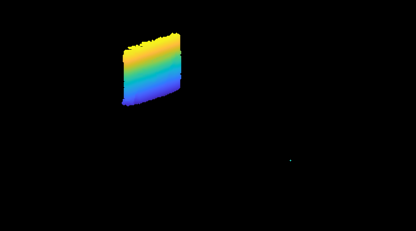

pcshow(ptCloud)

find the points within the region of ROI

tic

baseheight = 478;

roi = [-50,40,200,300,-50,50];
indice = findPointsInROI(ptCloud,roi);
ptCloudClose = select(ptCloud,indice);
% pcshow(ptCloudClose)

As the generated reconstruction starts from the camera centre (0,0,0), it might be difficult to observe the depth information. So, we modified the coordinate system and set the ROI to only cover the scanned surface.

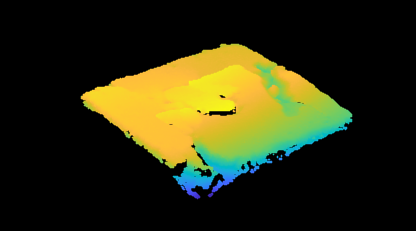

Object_changeyz = Object_found;
Object_changeyz(:,:,1) = Object_found(:,:,1);
Object_changeyz(:,:,2) = Object_found(:,:,3);
Object_changeyz(:,:,3) = -Object_found(:,:,2);
ptCloud_changeyz = pointCloud(Object_changeyz);
roi_changeyz = [-100,40,-100,100,-289,-230];
indice_changeyz = findPointsInROI(ptCloud_changeyz,roi_changeyz);
ptCloudClose_changeyz = select(ptCloud_changeyz,indice_changeyz);
pcshow(ptCloudClose_changeyz)


toc

Elapsed time is 8.755328 seconds.


I put the top view of the scanned specimen 1-2 here for comparison.

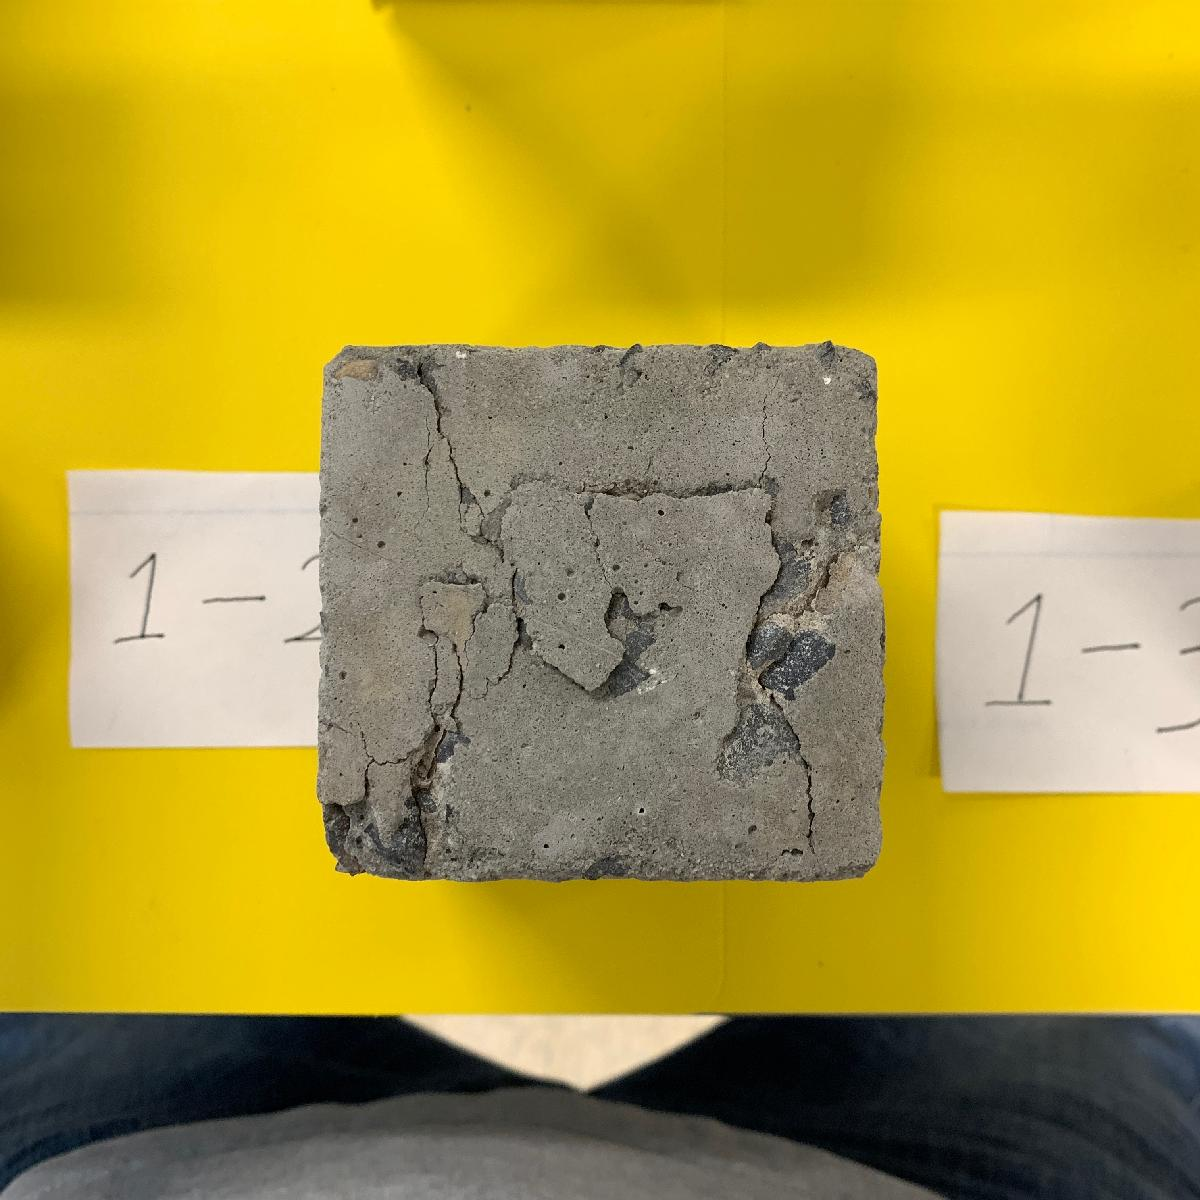

If you want to have a more clear view of some regions, you can use the following code to generate a specific point cloud not just a zoom-in view (which would not change the colour bar).

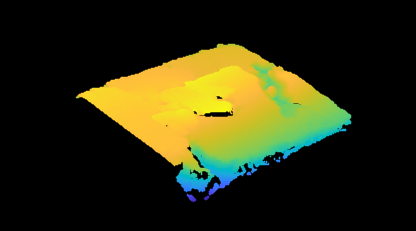

Object_changeyz = Object_found;
Object_changeyz(:,:,1) = Object_found(:,:,1);
Object_changeyz(:,:,2) = Object_found(:,:,3);
Object_changeyz(:,:,3) = -Object_found(:,:,2);
ptCloud_changeyz = pointCloud(Object_changeyz);

roi_changeyz = [-35,40,-100,100,-289,-230];

indice_changeyz = findPointsInROI(ptCloud_changeyz,roi_changeyz);
ptCloudClose_changeyz = select(ptCloud_changeyz,indice_changeyz);
pcshow(ptCloudClose_changeyz)

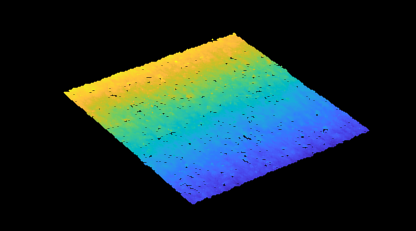


roi_pick = [-10,0,-29,-19,-300,-200];

indice_pick = findPointsInROI(ptCloudClose_changeyz,roi_pick);
ptCloudClose_changeyz_pick = select(ptCloudClose_changeyz,indice_pick);
pcshow(ptCloudClose_changeyz_pick)